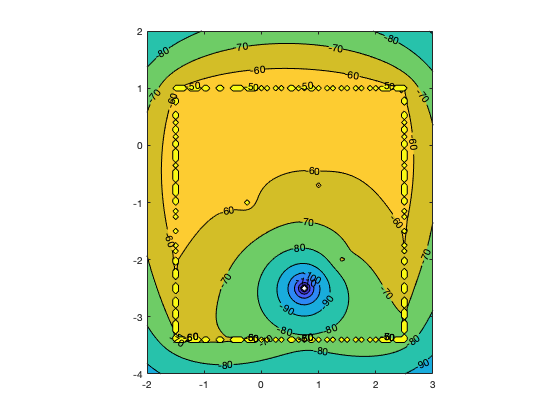

clf;
% create a meshgrid
[x,y]=meshgrid(-2:0.05:3,-4:0.05:2);

% define barrel and obstacles
v = 20*(log(sqrt((x-0.75).^2 + (y + 2.5).^2))) - 2*log(sqrt((x+0.25).^2 + (y+1).^2)) - 0.4*log(sqrt((x-1).^2 + (y+0.7).^2)) - 2.5*log(sqrt((x-1.41).^2 + (y+2).^2));

% define sources at lines for walls
for a = -1.5:0.01:2.5
    v = v - 0.05*log(sqrt((x-a).^2 + (y-1).^2));
    v = v - 0.05*log(sqrt((x-a).^2 + (y+3.4).^2));
end

for b = -3.37:0.01:1
    v = v - 0.05*log(sqrt((x+1.5).^2 + (y-b).^2));
    v = v - 0.05*log(sqrt((x-2.5).^2 + (y-b).^2));
end

% draw contours
contourf(x, y, v, 'k', 'ShowText', 'On');
axis equal;


$$V\left(x,y\right)=20*\ln \sqrt{{\left(x-0\ldotp 75\right)}^2 +{\left(y+2\ldotp 5\right)}^2 }-2*\ln \sqrt{{\left(x+0\ldotp 25\right)}^2 +{\left(y+1\right)}^2 }-2\ldotp 5*\ln \sqrt{{\left(x-1\ldotp 41\right)}^2 +{\left(y+2\right)}^2 }-0\ldotp 4*\ln \sqrt{{\left(x-1\right)}^2 +{\left(y+0\ldotp 7\right)}^2 }$$


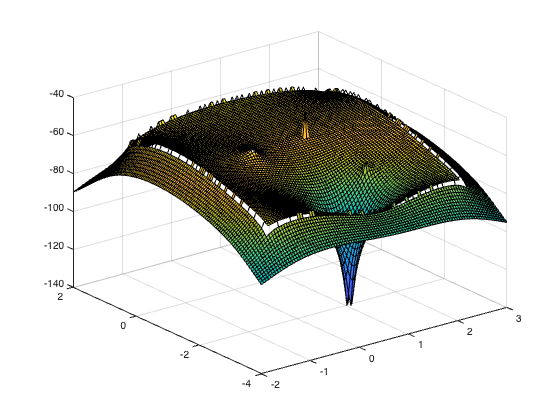

% surface plot
surf(x, y, v);

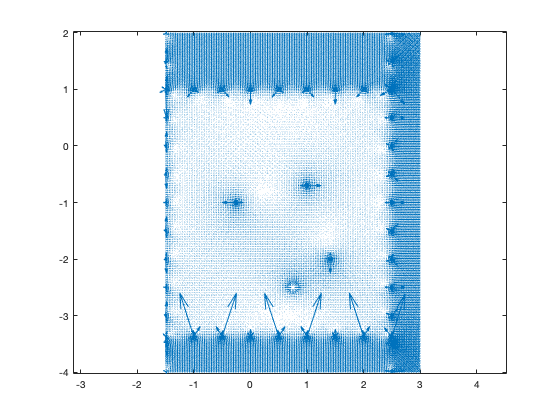

% quiver plot
clf;
% create a meshgrid
[x,y]=meshgrid(-1.5:0.03:3,-4:0.03:2);

fx = ((x-0.75)./((x-0.75).^2+(y+2.5).^2)) - ((x+0.25)./((x+0.25).^2+(y+1).^2)) - ((x-1.41)./((x-1.41).^2+(y+2).^2)) - ((x-1)./((x-1).^2+(y+0.7).^2));
fy = ((y+2.5)./((x-0.75).^2+(y+2.5).^2)) - ((y+1)./((x+0.25).^2+(y+1).^2)) - ((y+2)./((x-1.41).^2+(y+2).^2)) - ((y+0.7)./((x-1).^2+(y+0.7).^2));

for a = -1.5:0.5:2.5
    fx = fx - ((x-a)./((x-a).^2 + (y-1).^2));
    fy = fy - ((y-1)./((x-a).^2 + (y-1).^2));

    fx = fx - ((x-a)./((x-a).^2 + (y+3.4).^2));
    fy = fy - ((y+3.37)./((x-a).^2 + (y+3.4).^2));
end

for b = -4:0.5:2
    fx = fx - ((x+1.5)./((x+1.5).^2 + (y-b).^2));
    fy = fy - ((y-b)./((x+1.5).^2 + (y-b).^2));
 
    fx = fx - ((x-2.5)./((x-2.5).^2 + (y-b).^2));
    fy = fy - ((y-b)./((x-2.5).^2 + (y-b).^2));
end
quiver(x,y,fx,fy,20)
axis equal

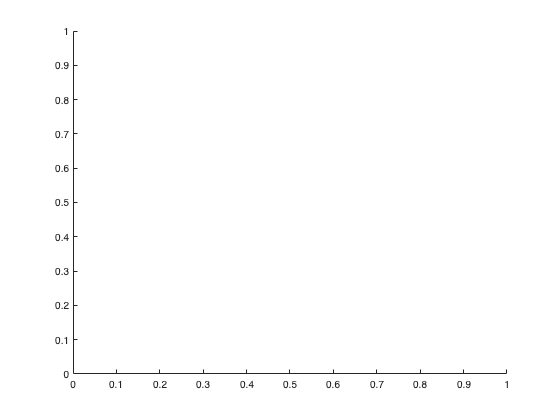

final_positions = [];

% the wheel base of the robot
wheelBase = 0.235;              % meters

% step size scaling factor
lambda = 0.01;

% setup symbolic expressions for the function and gradient
syms x y;

f = 20*(log(sqrt((x-0.75).^2 + (y + 2.5).^2))) - 2*log(sqrt((x+0.25).^2 + (y+1).^2)) - 0.4*log(sqrt((x-1).^2 + (y+0.7).^2)) - 2.5*log(sqrt((x-1.41).^2 + (y+2).^2));

grad = gradient(f, [x, y]);

% the problem description tells us to the robot starts at position 1, -1
% with a heading aligned to the y-axis
heading = [1; 0];
position = [0; 0];

angularSpeed = 0.2;  % radians / second (set higher than real to help with testing)
linearSpeed = 0.2;  % meters / second

% stop the robot's wheels in case they are running from before
pause(2);

% put the Neato in the starting location
% wait a little bit for the robot to land after being positioned
pause(2);

% set a flag to control when we are sufficiently close to the maximum of f
counter = 23;
while counter > 0
    % get the gradient
    gradValue = -1*double(subs(grad, {x, y}, {position(1), position(2)}));
    % calculate the angle to turn to align the robot to the direction of
    % gradValue. 
    crossProd = cross([heading; 0], [gradValue; 0]);

    % if the z-component of the crossProd vector is negative that means we
    % should be turning clockwise and if it is positive we should turn
    % counterclockwise
    turnDirection = sign(crossProd(3));

    % as stated above, we can get the turn angle from the relationship
    % between the magnitude of the cross product and the angle between the
    % vectors
    turnAngle = asin(norm(crossProd)/(norm(heading)*norm(gradValue)));

    % this is how long in seconds to turn for
    turnTime = double(turnAngle) / angularSpeed;

    % record the start time and wait until the desired time has elapsed

    heading = gradValue;

    % this is how far we are going to move
    forwardDistance = norm(gradValue*lambda);
    % this is how long to take to move there based on desired linear speed
    forwardTime = forwardDistance / linearSpeed;
    % start the robot moving

    % record the start time and wait until the desired time has elapsed

    % update the position for the next iteration
    position = position + (gradValue*lambda);
    final_positions = [final_positions position];
    counter = counter - 1;
end
clf
hold on;

% create a meshgrid
[x,y]=meshgrid(-2:0.05:3,-4:0.05:2);

% define barrel and obstacles
v = 20*(log(sqrt((x-0.75).^2 + (y + 2.5).^2))) - 2*log(sqrt((x+0.25).^2 + (y+1).^2)) - 0.4*log(sqrt((x-1).^2 + (y+0.7).^2)) - 2.5*log(sqrt((x-1.41).^2 + (y+2).^2));

% define sources at lines for walls
for a = -1.5:0.01:2.5
    v = v - 0.05*log(sqrt((x-a).^2 + (y-1).^2));
    v = v - 0.05*log(sqrt((x-a).^2 + (y+3.4).^2));
end

for b = -3.37:0.01:1
    v = v - 0.05*log(sqrt((x+1.5).^2 + (y-b).^2));
    v = v - 0.05*log(sqrt((x-2.5).^2 + (y-b).^2));
end

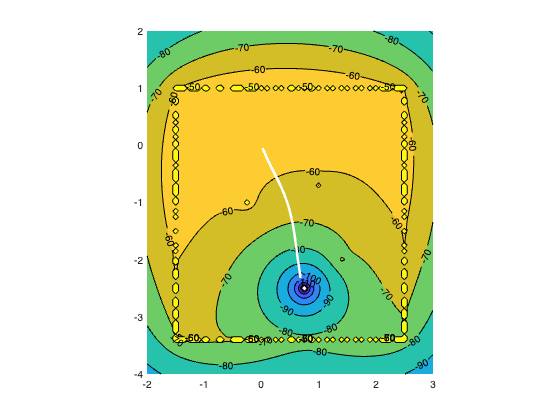


% draw contours
contourf(x, y, v, 'k', 'ShowText', 'On');
axis equal;
p = plot(final_positions(1, :), final_positions(2, :), 'w'); set(p,'LineWidth',2.5)